% --- DATOS DEL PROBLEMA ---
area = [0.20, 0.44, 0.79, 1.23, 1.77];
t_exp = [4.05, 5.49, 6.68, 8.34, 9.21];
t_err = [0.26, 0.17, 0.46, 0.11, 0.48];
t_teo = [3.94, 5.43, 7.06, 8.70, 10.36];

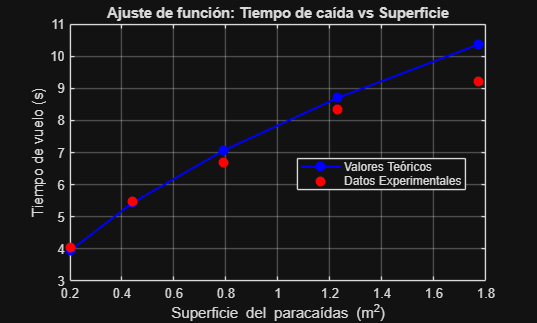

% --- GRAFICADO TEORICO-EXPERIMENTAL ---
figure;
hold on;
grid on;
box on;

plot(area, t_teo, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor', 'b', ...
    'DisplayName', 'Valores Teóricos');

plot(area, t_exp, 'or', 'MarkerSize', 6, 'LineWidth', 1.5, ...
    'MarkerFaceColor', 'r', 'DisplayName', 'Datos Experimentales');

title('Ajuste de función: Tiempo de caída vs Superficie');
xlabel('Superficie del paracaídas (m^2)');
ylabel('Tiempo de vuelo (s)');

legend('show', 'Location', 'best');

hold off;

% --- FUNCIONES DEL PERCEPTRON ---
T = @(A,c1,c2) c1*log(exp(c2*A)+sqrt(exp(2*c2*A)-1))./sqrt(A);
L = @(t_exp,area,c1,c2) sum((T(area,c1,c2)-t_exp).^2)/2;

% --- DERIVADAS ---
dTc1 = @(A,c1,c2) log(exp(c2*A)+sqrt(exp(2*c2*A)-1))./sqrt(A);
dTc2 = @(A,c1,c2) c1 .* sqrt(A) .* exp(c2*A) ./ sqrt(exp(2*c2*A) - 1);

dLc1 = @(t_exp,area,c1,c2) sum((T(area,c1,c2)-t_exp).*dTc1(area,c1,c2))

dLc1 = function_handle with value:
    @(t_exp,area,c1,c2)sum((T(area,c1,c2)-t_exp).*dTc1(area,c1,c2))


dLc2 = @(t_exp,area,c1,c2) sum((T(area,c1,c2)-t_exp).*dTc2(area,c1,c2))

dLc2 = function_handle with value:
    @(t_exp,area,c1,c2)sum((T(area,c1,c2)-t_exp).*dTc2(area,c1,c2))


Etapa 5 Loss 12.6319 c1 = 1.3138 c2 = 3.0942
Etapa 10 Loss 4.2951 c1 = 1.5515 c2 = 3.1833
Etapa 15 Loss 1.8061 c1 = 1.6788 c2 = 3.2383
Etapa 20 Loss 1.1337 c1 = 1.7436 c2 = 3.2697
Etapa 25 Loss 0.9615 c1 = 1.7754 c2 = 3.2876
Etapa 30 Loss 0.9178 c1 = 1.7904 c2 = 3.2983
Etapa 35 Loss 0.9057 c1 = 1.7969 c2 = 3.3053
Etapa 40 Loss 0.9013 c1 = 1.7993 c2 = 3.3106
Etapa 45 Loss 0.8988 c1 = 1.7997 c2 = 3.3149
Etapa 50 Loss 0.8967 c1 = 1.7992 c2 = 3.3188
Etapa 55 Loss 0.8948 c1 = 1.7981 c2 = 3.3225
Etapa 60 Loss 0.8929 c1 = 1.7968 c2 = 3.3260
Etapa 65 Loss 0.8910 c1 = 1.7954 c2 = 3.3296
Etapa 70 Loss 0.8891 c1 = 1.7939 c2 = 3.3330


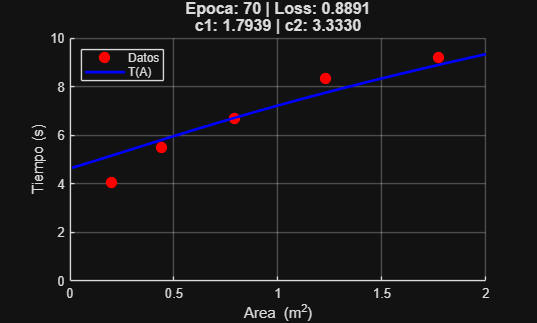


% --- PARAMETROS INICIALES ---
c1 = 1;
c2 = 3;

c1_new = 0;
c2_new = 0;

% --- PARAMETROS DEL ALGORITMO ---
epocas = 70;
nu = 0.0015;

loss_history = zeros(1, epocas);

% --- INICIALIZACION DEL GIF ---
figure(1)
filename = 'animacion_gradiente.gif';

x_limits = [0 2]; 
y_limits = [0 10];

area_smooth = linspace(0, 2, 200);

% --- ALGORITMO DE DESCENSO DE GRADIENTE ---
for epoca = 1:epocas

    loss_val = L(t_exp,area,c1,c2);
    loss_history(epoca) = loss_val;

    if mod(epoca,5) == 0
        fprintf('Etapa %d Loss %.4f c1 = %.4f c2 = %.4f\n', epoca, loss_val, c1, c2);
    end
    
    % --- GRAFICADO ---
    clf; 
    hold on;
    plot(area, t_exp, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', 'Datos');
    T_pred = T(area_smooth, c1, c2);
    plot(area_smooth, T_pred, 'b-', 'LineWidth', 2,'DisplayName', 'T(A)');

    grid on;
    axis([x_limits y_limits]);
    legend('Location', 'northwest');
    xlabel('Area (m^2)');
    ylabel('Tiempo (s)');
    
    title_str = sprintf('Epoca: %d | Loss: %.4f\nc1: %.4f | c2: %.4f', ...
                        epoca, loss_history(epoca), c1, c2);
    title(title_str, 'FontSize', 12, 'FontWeight', 'bold');
    
    hold off;
    drawnow; 

    % --- GUARDADO DEL GIF ---
    frame = getframe(1); 
    im = frame2im(frame); 
    [imind, cm] = rgb2ind(im, 256); 
    
    % Escribir en el archivo GIF
    if epoca == 1 
        % Primera imagen: crea el archivo
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1); 
    else 
        % Siguientes imágenes: añade al archivo
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1); 
    end

    % --- ACTUALIZACION DE LOS PARAMETROS ---
    c1_new = c1 - nu*dLc1(t_exp,area,c1,c2);
    c2_new = c2 - nu*dLc2(t_exp,area,c1,c2);
    
    c1 = c1_new;
    c2 = c2_new;
    
    
end

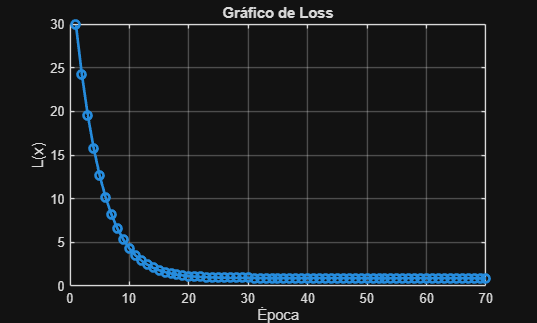


% --- GRAFICADO DE LOSS ---
figure;                 
plot(loss_history, '-o', 'LineWidth', 2); 

title('Gráfico de Loss');
xlabel('Época');
ylabel('L(x)');
grid on;